%  单面点云数据处理
%% 数据导入
clc;
clear all;

## 单面点云拟合

filepath = "C:\Users\10571\Desktop\t1\轮廓法 ssy\XIEQIE\AA.txt";%单面点云路径
Data = importdata(filepath);
ImpData = Data.data;
%平移对准
% M = [1,0,0;0,cosd(9),sind(9);0,-sind(9),cosd(9)];
% ImpData = ImpData*M';
x0 = ImpData(:,1); y0 = ImpData(:,2); z0 = ImpData(:,3);
%旋转调整基准面
[y0,z0] = Re(y0,z0);
n0 = length(x0);
a0 = [x0,y0,z0,ones(n0,1)];
u0 = [0,-min(abs(y0)),-mean(z0)]; 
Tr0 = [1,0,0,u0(1);0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
A0 = a0*Tr0';
%%%%%%%%%%%%%%%%%%%
% theta = -180;
% M = [A0(:,1),A0(:,2)]*[cosd(theta),-sind(theta);sind(theta),cosd(theta)]';
% ImpData = [M(:,1),M(:,2),A0(:,3)];
%%%%%%%%%%%%%%%%%%
ImpData = [A0(:,1),A0(:,2),A0(:,3)];

## 双面点云拟合

%%%%%%%%%%%%%%%%%使用双面点云拟合时将单面代码行注释掉
%%%%%%%%%%%%%%%%%不要注释第7行代码避免最后保存代码报错
% 点云对应路径
% data1 = importdata("E:\华龙\华龙rs\7104\7104-3\7104-3-B.txt");
% data2 = importdata("E:\华龙\华龙rs\7104\7104-3\7104-3-A.txt");
% %点云配准
% x0 = data1.data(:,1); y0 = data1.data(:,2); z0 = data1.data(:,3);
% [x0,z0] = Re(x0,z0);
% x1 = data2.data(:,1); y1 = data2.data(:,2); z1 = data2.data(:,3);
% [x1,z1] = Re(x1,z1);
% n0 = length(x0);
% a0 = [x0,y0,z0,ones(n0,1)];
% u0 = [0,-min(abs(y0)),-mean(z0)]; 
% Tr0 = [1,0,0,0;0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
% A0 = a0*Tr0'; x0 = A0(:,1); y0 = A0(:,2); z0 = A0(:,3);
% n1 = length(x1);
% a1 = [x1,y1,z1,ones(n1,1)];
% u1 = [0,-min(abs(y1)),-mean(z1)]; 
% Tr1 = [1,0,0,0;0,1,0,u1(2);0,0,1,u1(3);0,0,0,1];
% A1 = a1*Tr1'; x1 = A1(:,1); y1 = A1(:,2); z1 = A1(:,3);
% % %%%%%%%%%%%%%%%旋转180配准情况
% % theta = -180;
% % A = [x1,y1]*[cosd(theta),-sind(theta);sind(theta),cosd(theta)]';
% % x1 = A(:,1); y1 = A(:,2);
% %%平移对准
% % D = [0,max(y1)-max(y0),0];
% % TR = [1,0,0,0;0,1,0,D(2);0,0,1,0;0,0,0,1];
% % a0 = [x0,y0,z0,ones(n0,1)];
% % A0 = a0*TR'; x0 = A0(:,1); y0 = A0(:,2); z0 = A0(:,3);
% % %%%%%%%%%%%%%%%
% x = [-x1(x1>0);-x1(x1<0)]; y = [y1(x1>0);y1(x1<0)]; z = [z1(x1>0);z1(x1<0)];
% data1.data = [x0,y0,z0];
% data2.data = [x,y,z];
% ImpData = [data1.data;data2.data];

## 曲面分解

% %分解为垂直截面和平行截面
alph = 9;
% %平移
% TR = [1,0,0,0;0,1,0,-max(ImpData(:,2))./2;0,0,1,0;0,0,0,1];
% A = [ImpData,ones(length(ImpData),1)];
% A = A*TR'; ImpData = A(:,1:3);
% %旋转
% M = [1,0,0;0,cosd(alph),-sind(alph);0,sind(alph),cosd(alph)];
% ImpData = ImpData*M';
zh = ImpData(:,3).*sind(alph);%%正常轮廓法截面变形
zv = ImpData(:,3).*cosd(alph);%%平行z轴方向变形

## 前处理

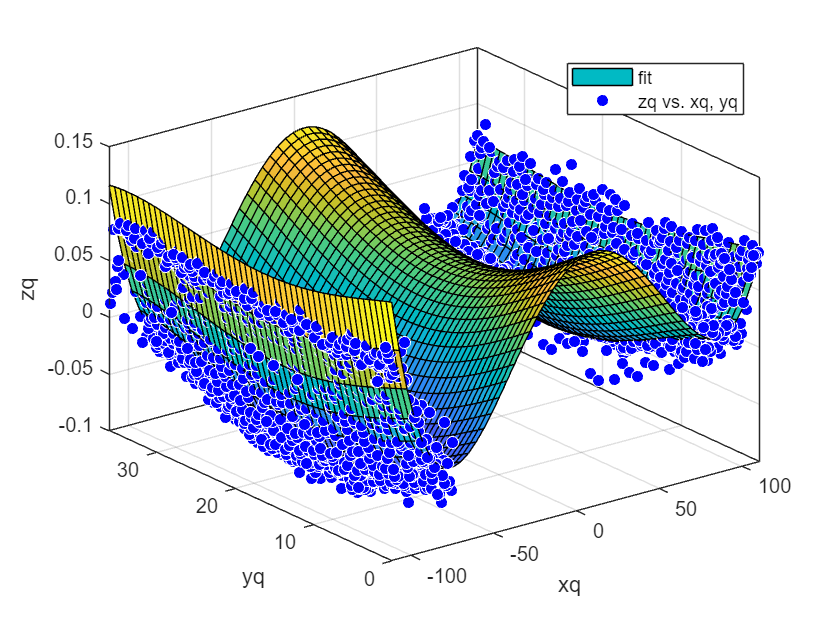

d = 1;%网格大小
[xq, yq, zq] = PreprocessDate(ImpData,d);
Tr0 = [1,0,0,0;0,1,0,max(abs(yq));0,0,1,0;0,0,0,1];
a0 = [xq,yq,zq,ones(length(xq),1)];
a0 = a0*Tr0';
yq = a0(:,2);
% [xq, yq, zq] = PreprocessDate([ImpData(:,1:2),zh],d);
%% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

0.11994 + -0.005696*Y + -1.8904e-06*Y*Y + 9.8706e-06*Y*Y*Y + -1.5133e-07*Y*Y*Y*Y + -5.4505e-07*X*Y + -6.407e-07*X*Y*Y + 1.1104e-08*X*Y*Y*Y + 3.4419e-07*X*X*Y + -1.032e-08*X*X*Y*Y + 6.948e-10*X*X*X*Y + 3.0504e-09*X*X*X*X 


disp(gof)

           sse: 0.6441
       rsquare: 0.8682
           dfe: 2695
    adjrsquare: 0.8675
          rmse: 0.0155




disp((max(zq)-min(zq)))

    0.1761



%% 保存拟合结果到文本
% c2 = cell2mat(struct2cell(gof));
% a = {s;c2};
% fileID = fopen(strcat(fileparts(filepath),'poly.txt'),'w');%%fileparts提取文件路径
% formatSpec = '%s %d %2.1f %s\n';
% [nrows,ncols] = size(a);
% for row = 1:nrows
%     fprintf(fileID,formatSpec,a{row,:}); % 注意此处不用{}，而是（）时，得到的字符串酱油引号，需注意
% end
% fclose(fileID);



